dataDirName = 'data';
if ~exist(dataDirName, 'dir')
  unzip('Data.zip', dataDirName);
end

dataDir = dir(dataDirName);
subjectFolders = dataDir(3:end);

## Data Exploration

subject1 = subjectFolders(1);
subject1Dir = dir(fullfile(dataDirName, subject1.name));
subject1BlockFiles = subject1Dir(3:end);

subject1Block1 = load(fullfile(dataDirName, subject1.name, subject1BlockFiles(1).name)).data;
subject1Block4 = load(fullfile(dataDirName, subject1.name, subject1BlockFiles(4).name)).data;

subject1Block1

subject1Block1 = struct with fields:
                   EEG: [34×56000 double]
                    fs: 100
                    TR: 2
                     u: [3×56000 double]
            m_category: [3×56000 double]
           m_coherence: [2×56000 double]
          EEG_noiseCov: [34×34 double]
       modulatory_type: {'face'  'car'  'house'  'high'  'low'}
         stimOnsetTime: [2.0350 5.5760 8.9020 10.9370 12.9560 15.8850 18.1190 20.3520 23.8280 26.2100 28.3440 31.3720 34.4840 36.5680 40.3070 44.3450 47.1740 50.8140 53.4450 55.9600 59.7330 61.7680 64.9450 67.3770 70.7530 74.0790 … ] (1×180 double)
               EEG_raw: [34×56000 double]
            EEG_filter: [30531×34 double]
                  fMRI: [6×56000 double]
                     L: [34×10177 double]
                     G: [10177×6 double]
                  mask: [10177×1 double]
                   Qx0: [10177×10177 double]
                   Qy0: [34×34 double]
              HRF_orig: [3200×3 double]
                   

fields = fieldnames(subject1Block1);
for i = 1:numel(fields)
    fieldData = subject1Block1.(fields{i});
    if isnumeric(fieldData) && ~isscalar(fieldData)
        fprintf('\nSummary for %s:\n', fields{i});
        disp(struct( ...
            'Size', size(fieldData), ...
            'Min', min(fieldData(:)), ...
            'Max', max(fieldData(:)), ...
            'Mean', mean(fieldData(:)), ...
            'Std', std(fieldData(:)) ...
        ));
    end
end


Summary for EEG:


    Size: [34 56000]
     Min: -53.4050
     Max: 50.6784
    Mean: 1.1901e-05
     Std: 1.2723




Summary for u:


    Size: [3 56000]
     Min: 0
     Max: 1
    Mean: 0.0054
     Std: 0.0730




Summary for m_category:


    Size: [3 56000]
     Min: 0
     Max: 1
    Mean: 0.2143
     Std: 0.4103




Summary for m_coherence:


    Size: [2 56000]
     Min: 0
     Max: 1
    Mean: 0.3214
     Std: 0.4670




Summary for EEG_noiseCov:


    Size: [34 34]
     Min: -203.7686
     Max: 396.1242
    Mean: 5.6548e-16
     Std: 65.2139




Summary for stimOnsetTime:


    Size: [1 180]
     Min: 2.0350
     Max: 527.9630
    Mean: 263.4657
     Std: 154.0518




Summary for EEG_raw:


    Size: [34 56000]
     Min: -286.9286
     Max: 490.3046
    Mean: -1.3135e-14
     Std: 12.3006




Summary for EEG_filter:


    Size: [30531 34]
     Min: -0.0204
     Max: 0.0200
    Mean: -5.9316e-13
     Std: 2.5548e-04




Summary for fMRI:


    Size: [6 56000]
     Min: -3.4847
     Max: 3.4256
    Mean: 2.3279e-16
     Std: 1.0000




Summary for L:


    Size: [34 10177]
     Min: -0.0409
     Max: 0.0336
    Mean: 3.9642e-07
     Std: 3.2877e-04




Summary for G:


    Size: [10177 6]
     Min: 0
     Max: 1
    Mean: 0.0029
     Std: 0.0538




Summary for mask:


    Size: [10177 1]
     Min: 1
     Max: 7
    Mean: 6.9466
     Std: 0.4643




Summary for Qx0:


    Size: [10177 10177]
     Min: 0
     Max: 0.7475
    Mean: 7.2827e-05
     Std: 0.0074




Summary for Qy0:


    Size: [34 34]
     Min: 0
     Max: 1
    Mean: 0.0294
     Std: 0.1690




Summary for HRF_orig:


    Size: [3200 3]
     Min: -0.0504
     Max: 0.0567
    Mean: 0.0025
     Std: 0.0175




Summary for HRF:


    Size: [16 3]
     Min: -8.2490
     Max: 10.5671
    Mean: 0.4949
     Std: 3.5156




Summary for whitenMatrix:


    Size: [34 34]
     Min: -171.4986
     Max: 0.9662
    Mean: -5.0441
     Std: 28.9887




Summary for unwhitenMatrix:


    Size: [34 34]
     Min: -17.7108
     Max: 11.3243
    Mean: -5.0441e-06
     Std: 1.8493




Summary for L_norm:


    Size: [34 30531]
     Min: -0.8932
     Max: 0.9373
    Mean: -2.8535e-19
     Std: 0.1715




Summary for L_3D:


    Size: [34 30531]
     Min: -0.0798
     Max: 0.0634
    Mean: 4.5789e-22
     Std: 7.5071e-04




Summary for L_project:


    Size: [34 10177]
     Min: -0.0737
     Max: 0.0853
    Mean: 1.5341e-21
     Std: 0.0011




Summary for L_reducerank:


    Size: [34 10177]
     Min: -0.0672
     Max: 0.0897
    Mean: -1.5892e-21
     Std: 0.0013




Summary for dipole_orientation:


    Size: [10177 3]
     Min: -1.0000
     Max: 1.0000
    Mean: -0.1634
     Std: 0.5538




Summary for sigma2_x:


    Size: [7 1]
     Min: 0.0461
     Max: 0.7475
    Mean: 0.4129
     Std: 0.2652



# Visualization

Initialize EEGLAB

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...


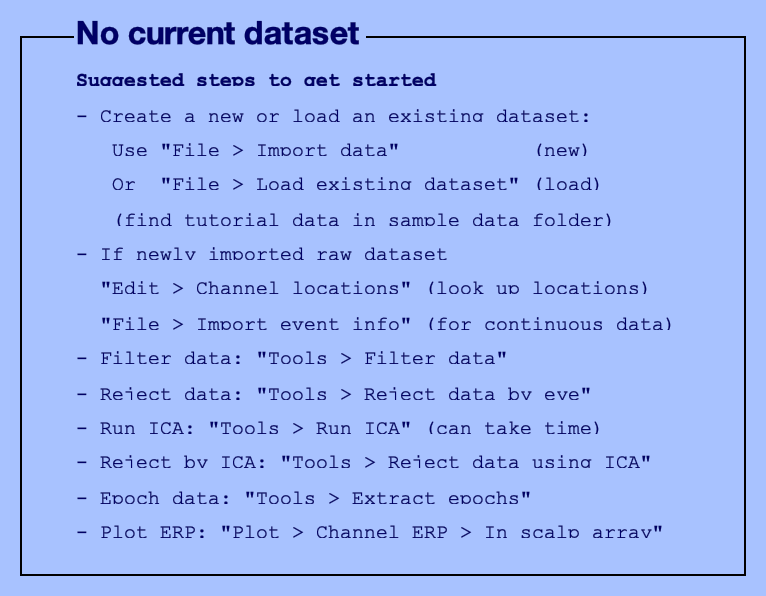

You are using the latest version of EEGLAB.


set(0, 'DefaultFigureVisible', 'on');
eeglab;

Create dataset and add channel labels

% Create EEG structure
EEG = pop_importdata('dataformat', 'array', 'data', subject1Block1.EEG, ...
                     'srate', subject1Block1.fs, 'nbchan', 34, 'chanlocs', []);

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (56000) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



% Add channel labels (optional, if you know them)
EEG.chanlocs = struct('labels', arrayfun(@(x) sprintf('Chan%d', x), 1:34, 'UniformOutput', false));

% Update EEG structure
EEG = eeg_checkset(EEG);

Add events and labels

% Convert onset times from seconds to sample points
stimSamples = round(subject1Block1.stimOnsetTime * subject1Block1.fs);

% Define event labels (from modulatory_type)
eventLabels = {'face', 'car', 'house'};

% Create event array
EEG.event = [];

for i = 1:numel(stimSamples)
    % Determine the event type from 'u' (one-hot encoded)
    eventTypeIdx = find(subject1Block1.u(:, stimSamples(i)) == 1);
    if ~isempty(eventTypeIdx)
        EEG.event(end + 1).type = eventLabels{eventTypeIdx};
        EEG.event(end).latency = stimSamples(i);
    end
end

% Update the EEG structure
EEG = eeg_checkset(EEG);

% Display event types and latencies
for i = 1:length(EEG.event)
    disp(['Event ', num2str(i), ': ', EEG.event(i).type, ', Latency: ', num2str(EEG.event(i).latency / EEG.srate), ' sec']);
end

Event 1: house, Latency: 2.04 sec
Event 2: house, Latency: 5.58 sec
Event 3: car, Latency: 8.9 sec
Event 4: house, Latency: 10.94 sec
Event 5: car, Latency: 12.96 sec
Event 6: car, Latency: 15.89 sec
Event 7: house, Latency: 18.12 sec
Event 8: face, Latency: 20.35 sec
Event 9: face, Latency: 23.83 sec
Event 10: face, Latency: 26.21 sec
Event 11: car, Latency: 28.34 sec
Event 12: car, Latency: 31.37 sec
Event 13: face, Latency: 34.48 sec
Event 14: car, Latency: 36.57 sec
Event 15: house, Latency: 40.31 sec
Event 16: car, Latency: 44.35 sec
Event 17: face, Latency: 47.17 sec
Event 18: car, Latency: 50.81 sec
Event 19: car, Latency: 53.45 sec
Event 20: car, Latency: 55.96 sec
Event 21: house, Latency: 59.73 sec
Event 22: car, Latency: 61.77 sec
Event 23: car, Latency: 64.94 sec
Event 24: face, Latency: 67.38 sec
Event 25: house, Latency: 70.75 sec
Event 26: house, Latency: 74.08 sec
Event 27: car, Latency: 77.87 sec
Event 28: house, Latency: 80.25 sec
Event 29: house, Latency: 83.33 sec
E

Create ERPs

epochWindow = [-0.2 1];

% Set time window around each event (-1 to +2 seconds)
EEG = pop_epoch(EEG, eventLabels, epochWindow);

pop_epoch():180 epochs selected
Epoching...
pop_epoch():180 epochs generated
pop_epoch(): checking epochs for data discontinuity



% Check baseline and data quality
EEG = pop_rmbase(EEG, [-200 0]); % Baseline from -0.2 to 0 sec

pop_rmbase(): Removing baseline...



% Recheck dataset integrity
EEG = eeg_checkset(EEG);

disp(['Number of epochs: ', num2str(EEG.trials)]);

Number of epochs: 180


Plot full EEG data with event markers

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


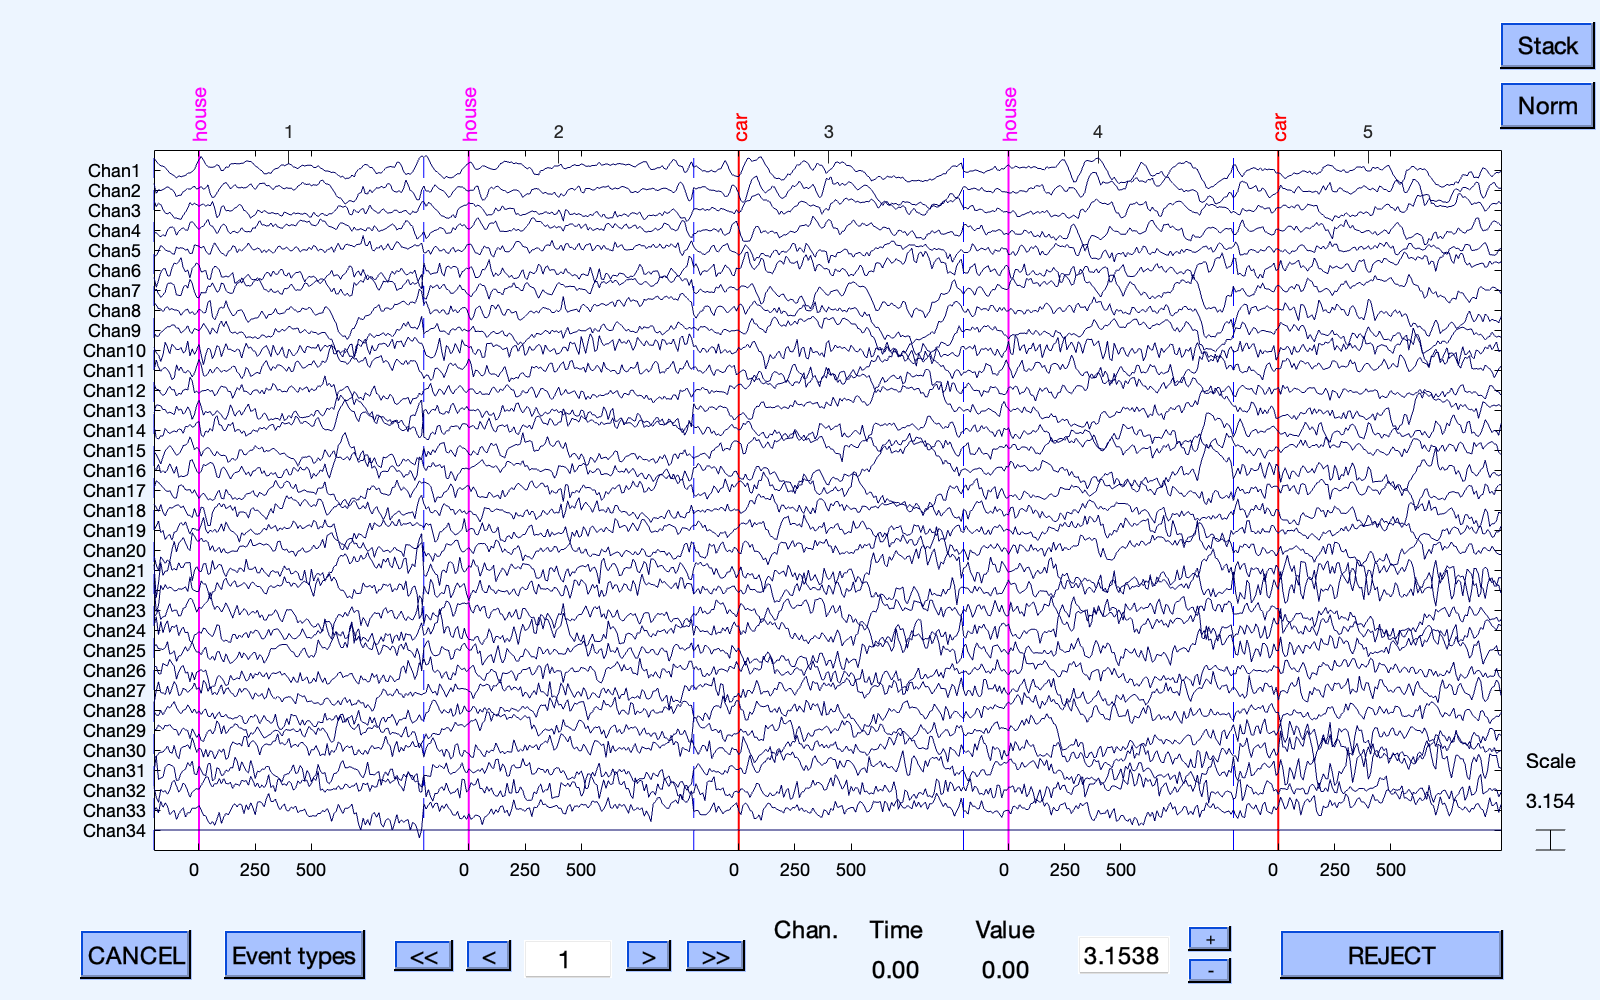

fig = figure;
pop_eegplot(EEG, 1, 1, 1);

Plot the average ERP for each channel to illustrate normal-looking ERPs

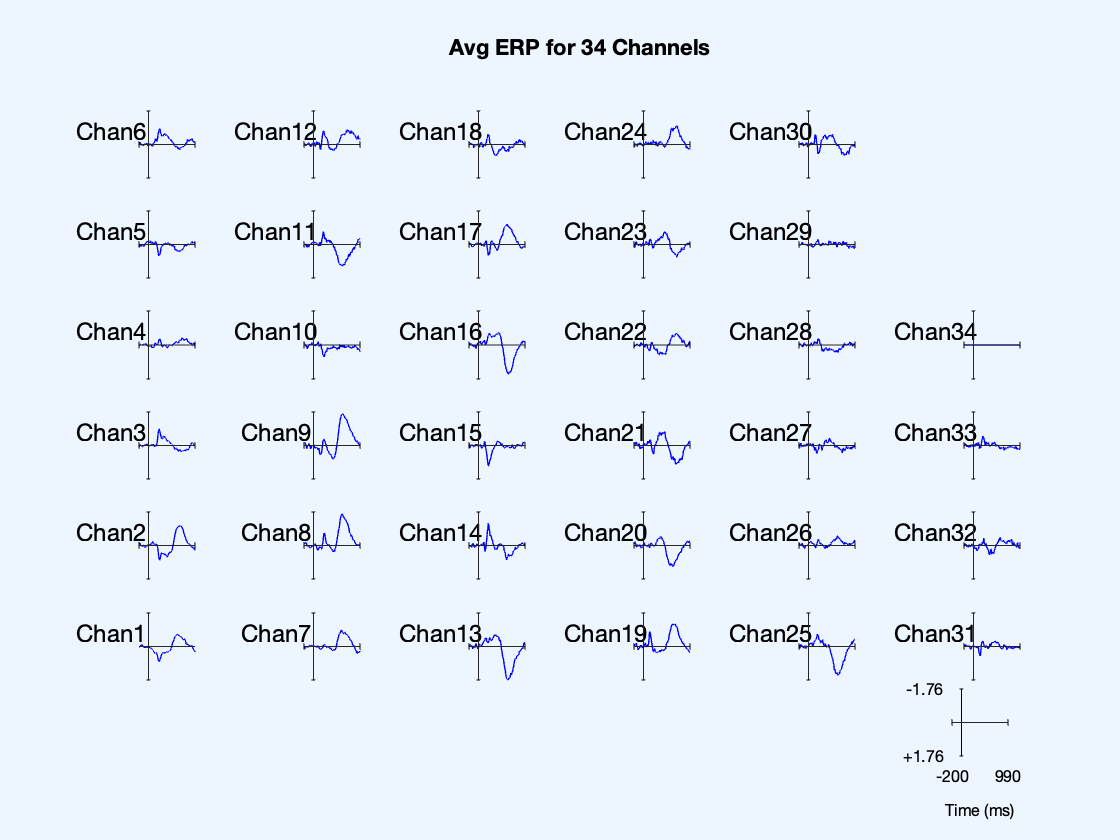

Plotting data using axis size [0.05,0.08]
limits: [xmin,xmax,ymin,ymax] = [-200.0 990.0 -1.76 1.76]
Plotting 1 traces of 120 frames with colors: 'b' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34


figure;
pop_plottopo(EEG, 1:34, 'Avg ERP for 34 Channels', 0);

Split dataset into each event type and display the average ERP for each event type for each channel to show variability

% Create datasets for each category
figure;
EEG_face = pop_selectevent(EEG, 'type', 'face');

Removing 120 trial(s)...
Pop_select: removing 120 unreferenced events


EEG_car = pop_selectevent(EEG, 'type', 'car');

Removing 120 trial(s)...
Pop_select: removing 120 unreferenced events


EEG_house = pop_selectevent(EEG, 'type', 'house');

Removing 120 trial(s)...
Pop_select: removing 120 unreferenced events


Plotting data using axis size [0.05,0.08]
limits: [xmin,xmax,ymin,ymax] = [-200.0 990.0 -2.55 2.55]
Plotting 3 traces of 120 frames with colors: 'b' 'r' 'g' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34
trace 2:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34
trace 3:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34


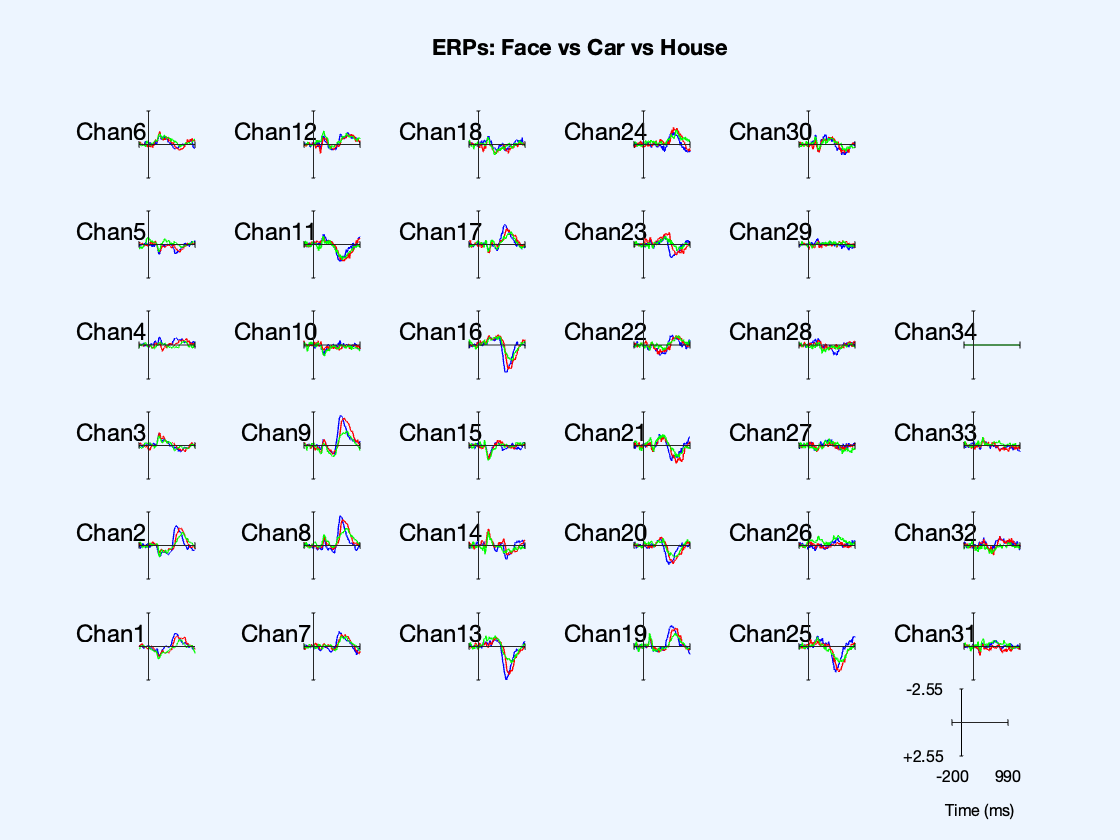

pop_comperp([EEG_face, EEG_car, EEG_house], 1, [1 2 3], [], ...
    'title', 'ERPs: Face vs Car vs House', ...
    'addall', 'on', 'std', 'off', 'addavg', 'off');

Display heatmap of trial-to-trial variability in the ERP signal for a single event type

imageOutputFolder = 'reports/figures/erp/car/heatmaps';
dataset = EEG_car;
title_name = 'Car ERP';

% Loop over all channels and create a heatmap for each one
for ch = 1:dataset.nbchan
    % Extract channel label
    ch_label = dataset.chanlocs(ch).labels;
    
    % Extract ERP data for this channel across all epochs
    ch_data = squeeze(dataset.data(ch, :, :));  % time x epochs
    
    % Create new figure
    fig = figure('Name', ['ERP Heatmap  - ', ch_label], 'NumberTitle', 'off', 'Visible', 'off');
    
    % Display heatmap
    imagesc(dataset.times, 1:size(ch_data, 2), ch_data');  % Transpose so trials are rows
    axis xy;  % Put time on X, trials on Y
    xlabel('Time (ms)');
    ylabel('Epoch');
    title([title_name, ' Heatmap for Channel ', ch_label]);
    colorbar;
    clim([-5 5]);

    filename = fullfile(imageOutputFolder, [ch_label, '.png']);
    saveas(fig, filename);
    % exportgraphics(fig, filename, 'Resolution', 150);  % Instead of saveas

    % Close the figure to avoid memory overload
    close(fig);
end

Trace all events' ERPs for an event type for comparison

dataset = EEG_car;
channel_label = 'Chan16';
channel_title = '16';
title_name = 'Car ERP';
imageOutputFolder = 'reports/figures/erp/car';

fig = figure('Visible','on');
channel_index = find(strcmp({dataset.chanlocs.labels}, channel_label));
channel_data = squeeze(dataset.data(channel_index, :, :));
plot(dataset.times, channel_data(:, 1:30));
xlabel('Time (ms)');
ylabel('Amplitude (µV)');
ylim([-5 5])
title([title_name, ' Trace for Channel ', channel_title]);
filename = fullfile(imageOutputFolder, [channel_label, '.png']);
saveas(fig, filename);
close(fig);

FFT of ERP avgs

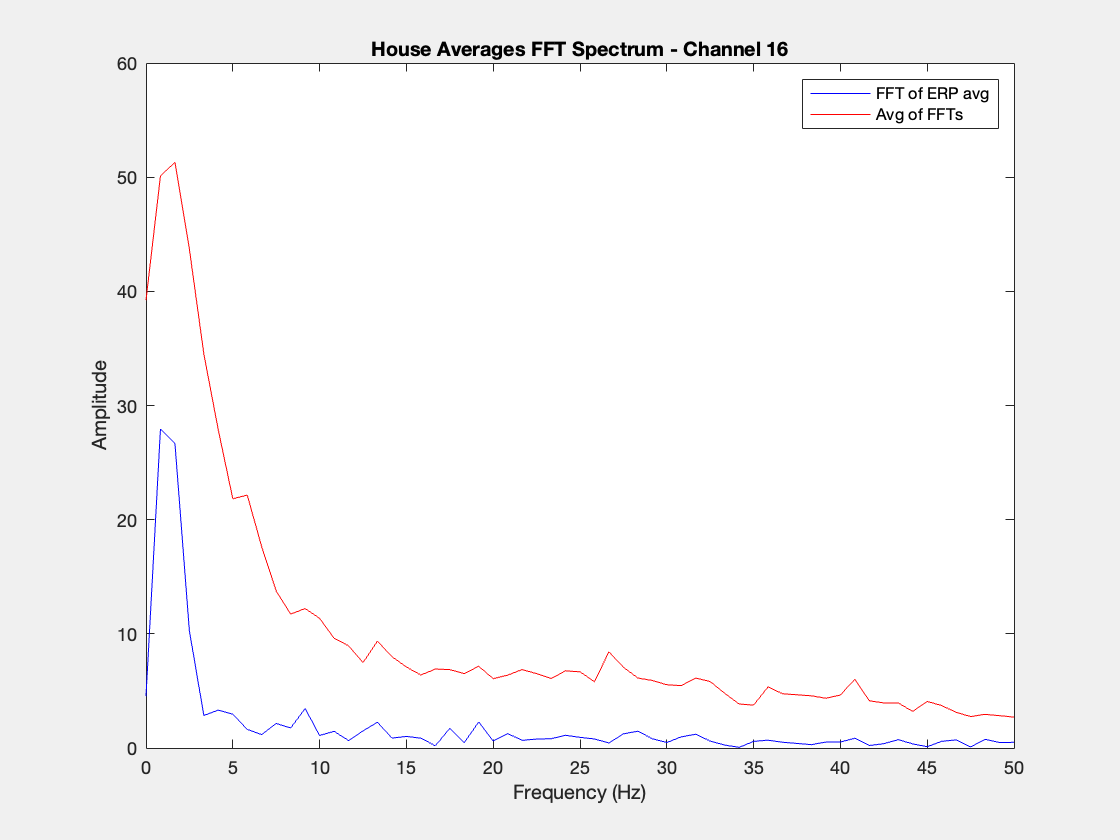

channel_label = 'Chan16';
channel_title = '16';
dataset = EEG_house;
title_name = 'House';

channel_index = find(strcmp({dataset.chanlocs.labels}, channel_label));

% Extract data (samples x epochs) for one channel
channel_data = squeeze(dataset.data(channel_index, :, :));

% FFT setup
Fs = EEG.srate;
N = size(channel_data, 1);           % Number of time samples
f = (0:N-1)*(Fs/N);                  % Frequency vector (full length)
half_n = floor(N/2)+1;              % Index for positive frequencies
f_pos = f(1:half_n);                % Positive frequency axis

erp_avg = mean(channel_data, 2);      % average waveform
fft_erp_avg = abs(fft(erp_avg));

fft_trials = abs(fft(channel_data));  % average of individual FFTs
fft_avg_trials = mean(fft_trials, 2);

% Plot both
f = (0:N-1)*(Fs/N);
figure('Visible','on');
plot(f(1:half_n), fft_erp_avg(1:half_n), 'b', f(1:half_n), fft_avg_trials(1:half_n), 'r');
legend('FFT of ERP avg', 'Avg of FFTs');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title([title_name, ' Averages FFT Spectrum - Channel ', channel_title]);

Overlay first 30

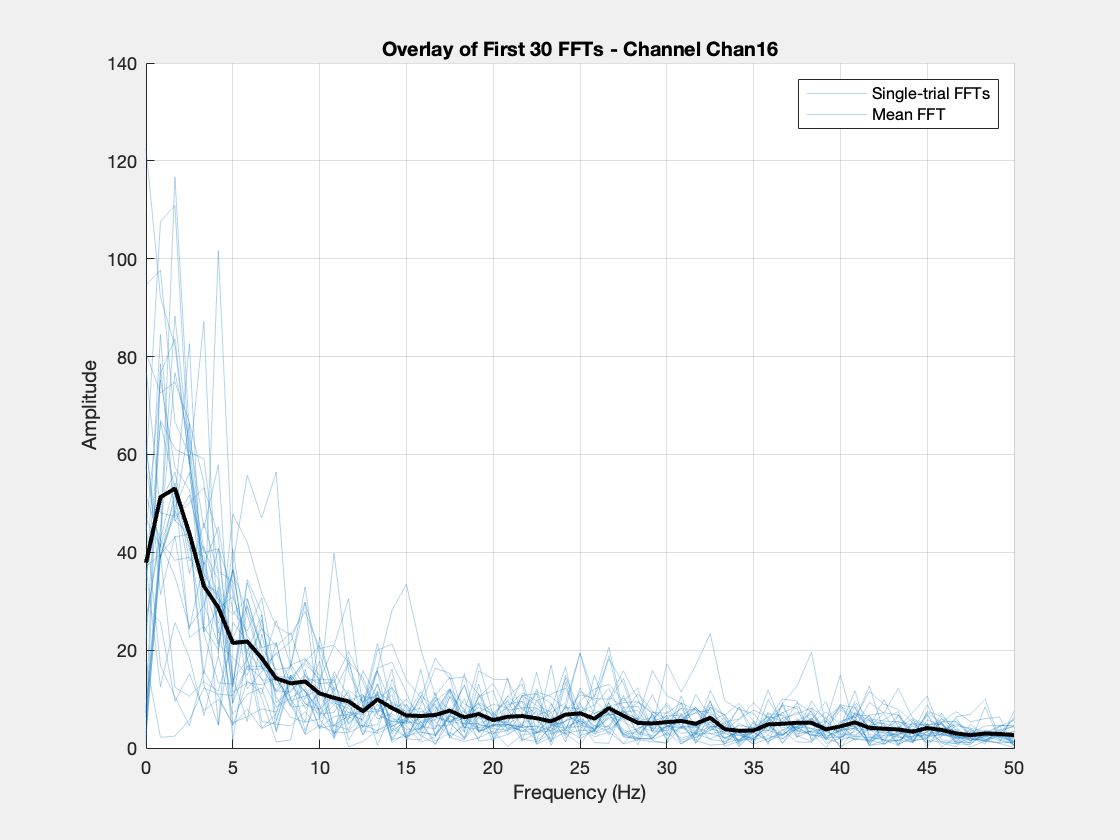


% Prepare figure
figure('Visible','on');
hold on;

% Loop through first 30 trials and plot FFTs
for i = 1:min(30, size(channel_data, 2))
    fft_trial = fft(channel_data(:, i));         % Full FFT
    fft_mag = abs(fft_trial(1:half_n));          % Magnitude of positive freqs
    plot(f_pos, fft_mag, 'Color', [0 0.447 0.741 0.3]);  % Light blue lines
end

% Optionally add mean spectrum
fft_all = abs(fft(channel_data));                % Full FFTs
mean_fft = mean(fft_all(1:half_n, 1:30), 2);      % Mean across first 30
plot(f_pos, mean_fft, 'k', 'LineWidth', 2);      % Bold black line

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title(['Overlay of First 30 FFTs - Channel ', channel_label]);
legend('Single-trial FFTs', 'Mean FFT');
grid on;

spectrogram heatmap

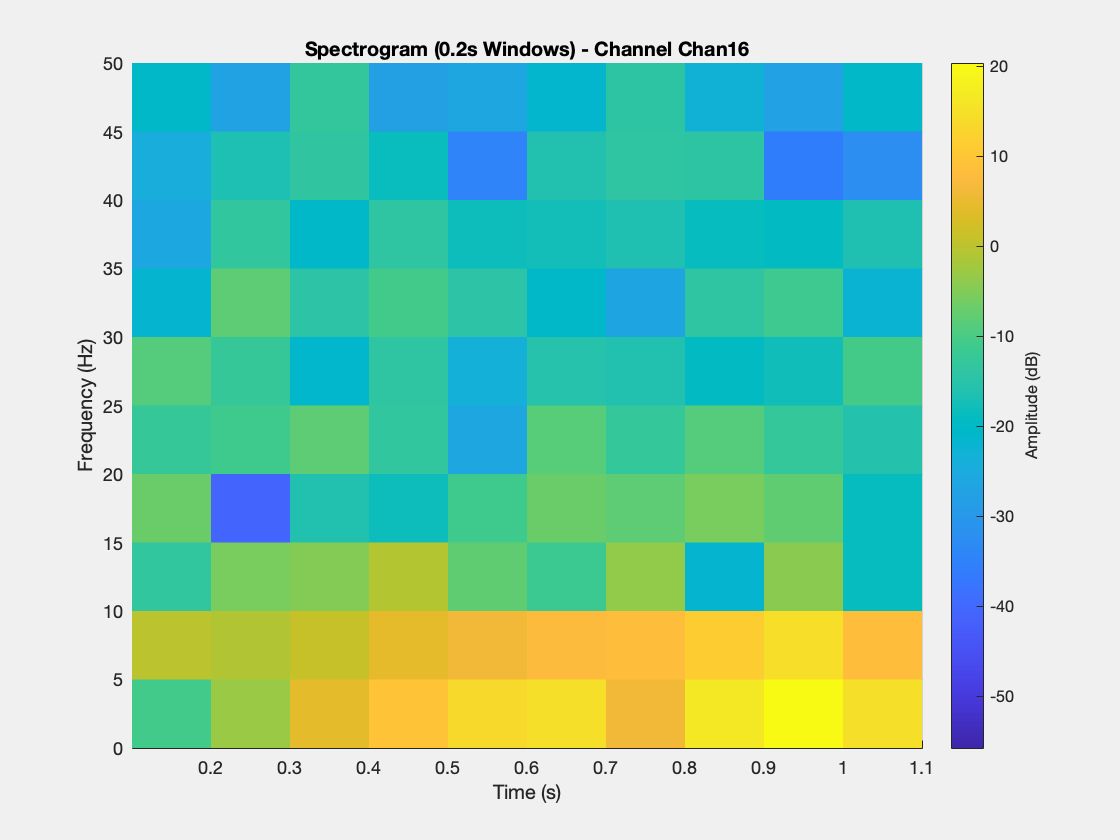

win_sec = 0.2;                % Window length in seconds
win_samples = round(win_sec * Fs);  % Window size in samples

% Use 50% overlap and 5 Hz resolution (DFT points)
overlap = round(0.5 * win_samples);
nfft = Fs / 5; % max(256, 2^nextpow2(win_samples));  % Zero padding to improve resolution

% Compute spectrogram
[S, F, T] = spectrogram(erp_avg, win_samples, overlap, nfft, Fs);

% Convert to amplitude or power
S_amp = abs(S);           % Amplitude
S_db = 20*log10(S_amp);   % dB scale (optional for power visualization)

% 3D Surface plot
figure('Visible','on');
surf(T, F, S_db, 'EdgeColor', 'none');
axis tight;
view(0, 90);  % Top-down view (use view(3) for angled 3D)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title(['Spectrogram (0.2s Windows) - Channel ', channel_label]);
colorbar;
ylabel(colorbar, 'Amplitude (dB)');

spectrogram waterfall

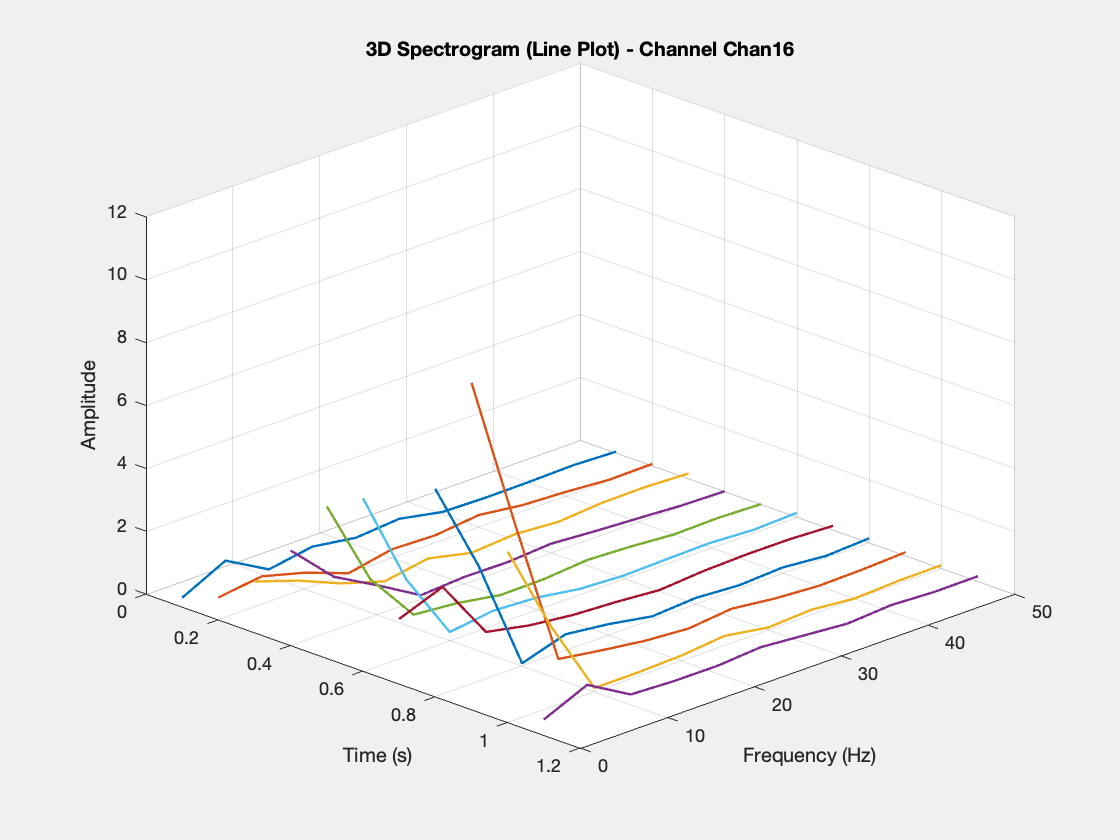


figure('Visible','on');
hold on;

% Plot each time slice as a 3D line
for ti = 1:length(T)
    plot3(T(ti) * ones(size(F)), F, S_amp(:, ti), 'LineWidth', 1.2);
end

xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Amplitude');
title(['3D Spectrogram (Line Plot) - Channel ', channel_label]);
view(45, 30);     % Adjust for better visibility
grid on;

power plot

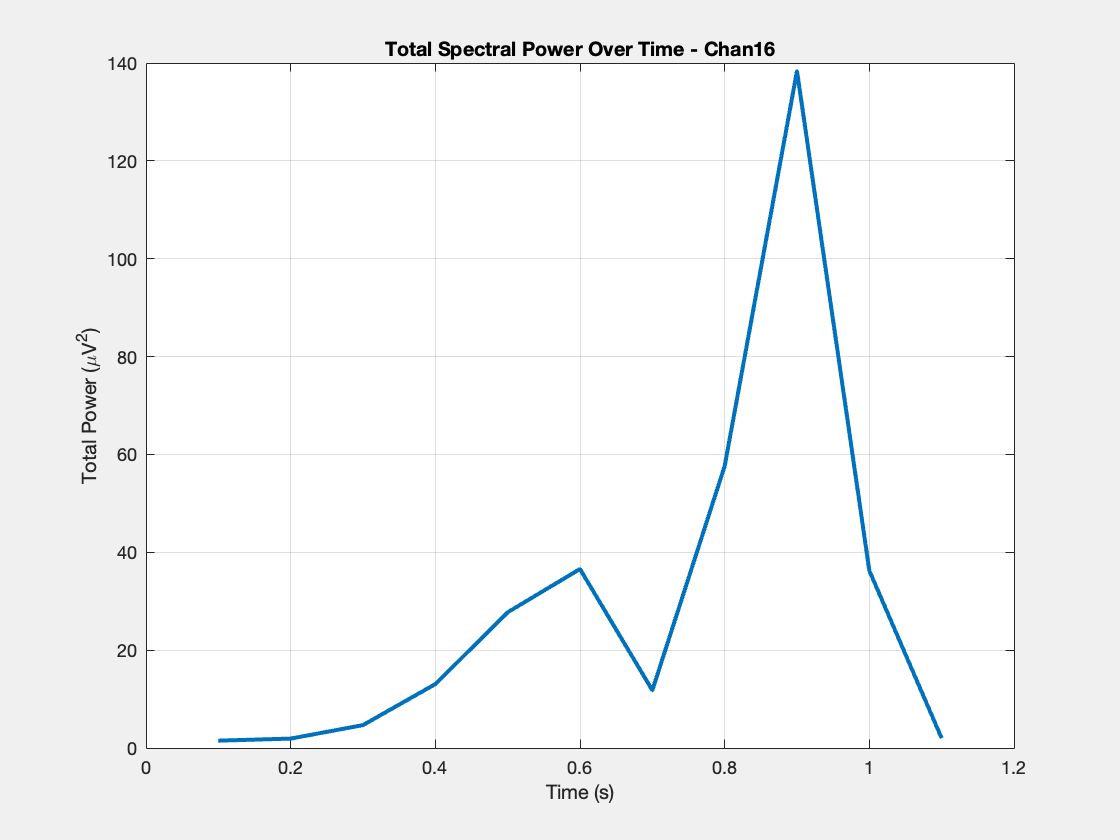

power_time = sum(abs(S).^2, 1);  % Power = magnitude squared

% Plot
figure('Visible','on');
plot(T, power_time, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Total Power (\muV^2)');
title(['Total Spectral Power Over Time - ', channel_label]);
grid on;

high freq amplitude plot

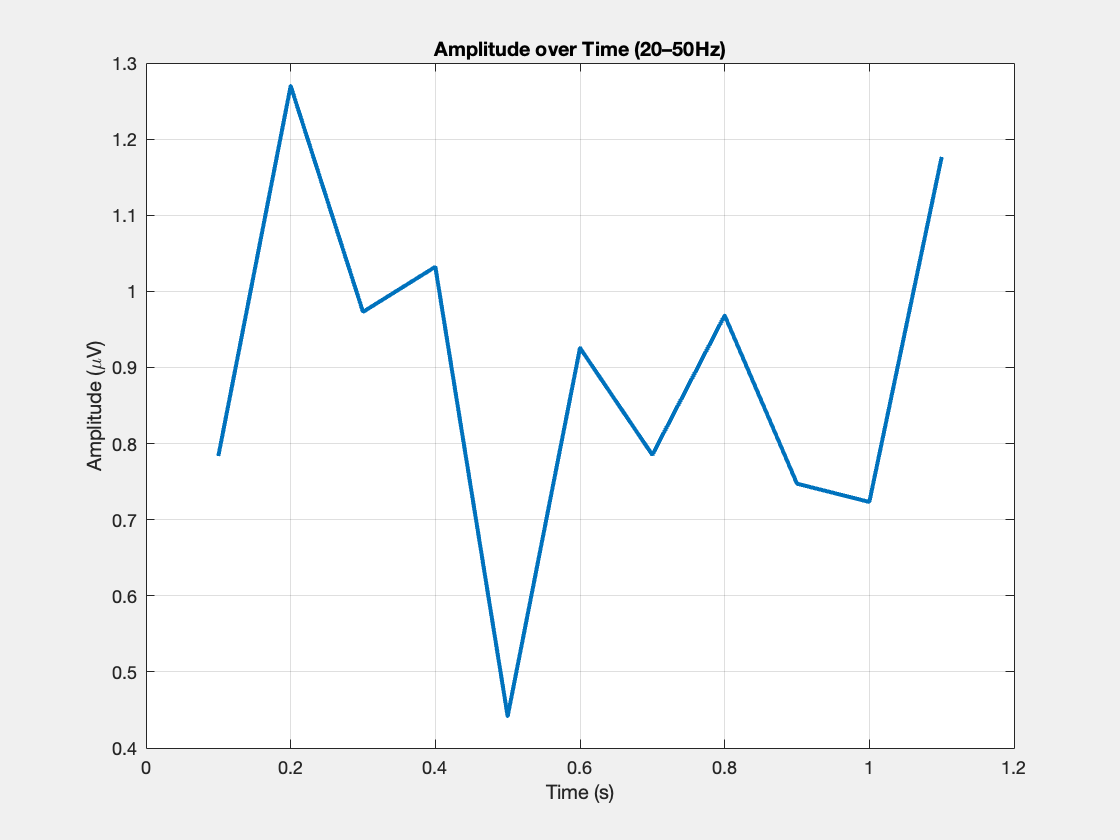

% Define frequency range of interest
freq_min = 20;  % Minimum frequency in Hz
freq_max = 40;  % Maximum frequency in Hz

% Identify indices corresponding to the desired frequency range
freq_indices = (F >= freq_min) & (F <= freq_max);

% Compute amplitude over time for the specified frequency range
amplitude_time = sum(abs(S(freq_indices, :)), 1);  % Sum of amplitudes

% Plot amplitude over time
figure('Visible','on');
plot(T, amplitude_time, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
title('Amplitude over Time (20–50 Hz)');
grid on;

high freq power plot

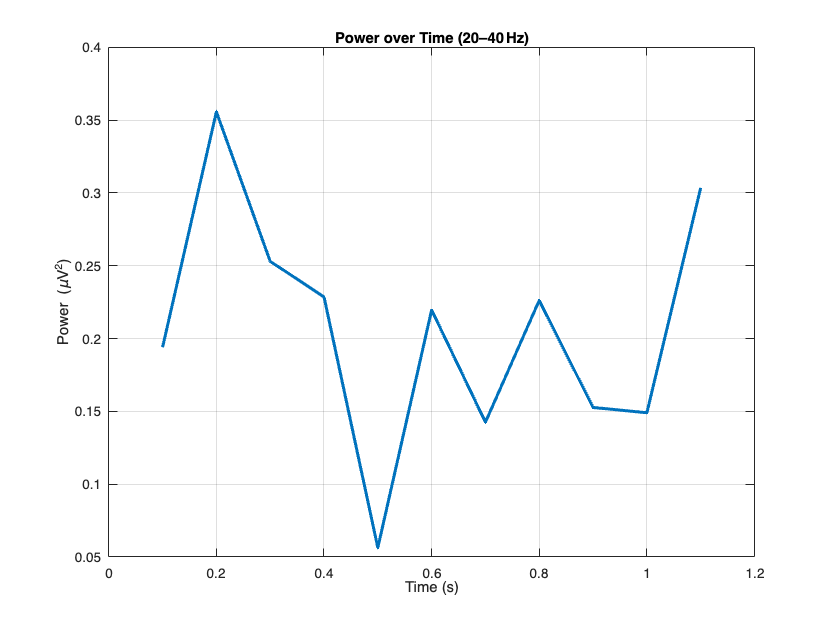

% Compute power over time for the specified frequency range
power_time = sum(abs(S(freq_indices, :)).^2, 1);  % Sum of squared magnitudes

% Plot power over time
figure;
plot(T, power_time, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power (\muV^2)');
title('Power over Time (20–40 Hz)');n 
grid on;

pop_saveset(EEG, 'filename', 'EEG_VisualTask.set', 'filepath', './');

Saving dataset...
